% GENERATE BODE PLOT OF SYSTEM BANDWIDTH

% Author: James Hope, Biosensing and Biorobotics Lab, 
% Department of Mechanical Engineering, University of Minnesota
% Contact: suhasabk@umn.edu

% Using kinematics function from Yuliya Smirnova, Copyright (c) 2019
% modified for compatibility with other functions 

% Using dynamics equations from Zhang et al 2012 doi:10.1017/S0263574711000622

clear all 

    % constants
    Lp = 0.34; 
    Ld = 0.656;
    Rf = 0.19;
    Rm = 0.1;
    
    tincr = 0.01;
    
% anglular offsets of delta motors from reference frame x-axis
kappa_1 = 6*pi/4;    % (rad)
kappa_2 = pi/6;     % (rad)
kappa_3 = 5*pi/6;   % (rad)
% anglular offsets of delta motors from reference frame x-axis
kappa = [kappa_1, kappa_2, kappa_3];

% position    
X = -0.4;
Y = -0.4;
Z = -0.6;
r_forw = [X;Y;Z];

%velocity
Xdot = 0;
Ydot = 0;
Zdot = 0;
r_dot = [Xdot;Ydot;Zdot];

% acceleration
r_dotdot = [0;0;0];


% joint position
[theta1, theta2, theta3, fl] = IKinemDelta2(X, Y, Z, Rm, Rf, Ld, Lp);
theta = [theta1;theta2;theta3];

% Zhang vectors
[e_1,e_2,e_3,u_1,u_2,u_3,w_1,w_2,w_3,v_1,v_2,v_3] = Zhangvectors(Rf,Rm,Ld,Lp,theta,r_forw,kappa);

% Jacobian
[Jq,Jx] = DeltaJacobian2(u_1,u_2,u_3,w_1,w_2,w_3,v_1,v_2,v_3,Lp);
Jinv = inv(Jq)*Jx

Jinv =     3.0926    2.7153    2.0296
   -2.1778   -2.0053   -1.1521
   -0.1398   -2.9987   -3.0677


J = inv(Jinv)

J =     0.8116    0.6752    0.2834
   -1.9621   -2.7697   -0.2579
    1.8809    2.6766   -0.0868



% joint vel accel
theta_dot = Jinv*r_dot;

[fr_dot] = f_r_dotcalc(u_1,u_2,u_3,w_1,w_2,w_3,v_1,v_2,v_3,Lp,Ld,r_dot);

theta_dotdot = Jinv*r_dot + fr_dot;

    
f_D = [0,0,0]';
        
g = 9.8;     % (m/s^2) accel. from gravity
z_hat = -[0 0 1]';

% system properties
mu_1 = 0.5; % (kg/m) of proximal linkage
mu_2 = 0.5; % (kg/m) of distal linkage
m_A = mu_1*Lp; % (kg) mass of proximal linkage
r_A = Lp/2;  % assume centre of gravity is halfway along the linkage
m_B = 0.1;  % (kg) lump mass at B
m_C = 1;     % (kg) mass of moving platform

% the inertia of the components in each kinematic chain:
I_A1 = 0.17;         % (kg.m^2) gearbox
I_A2 = mu_1*Lp^3/3;    % (kg.m^2) intermediate section
I_A3 = m_B*Lp^2;       % (kg.m^2) lump mass at B
I_A4 = 4*mu_2*Ld*Lp^2/3; % (kg.m^2) equivalent mass of distal links
I_A = I_A1 + I_A2 + I_A3 + I_A4;

Eta = m_C/I_A;
G = Eta*J'+inv(J);
Tau_a = I_A*G*r_dotdot; % Inertial torque
Tau_v = I_A*fr_dot;        % centrifuge/Coriolis torque
Tau_Ag = m_A*r_A*g*[cos(theta(1)) cos(theta(2)) cos(theta(3))]'; % gravitational torque from Delta arms
Tau_g = J'*m_C*g*z_hat + Tau_Ag;  % gravitational torque
Tau_d = J'*f_D;            % force exetered on delta platform by goniometer

JSIM = I_A*G

JSIM =     1.5497   -1.3140    2.3653
    0.1554   -3.2483    2.4017
    0.2500   -0.9736   -0.8190


% TSIM1 = Jinv'*JSIM*Jinv
TSIM = Jinv'*JSIM

TSIM =     4.4193    3.1465    2.1992
    3.1465    5.8655    4.0622
    2.1992    4.0622    4.5460




% x axis first

syms F_ext S_f S_p Y_v Y_r C_fb_pos C_fb_vel s v 

for n = 1:3

s = tf('s') 

% J = 1;
% Fext = 1;

% Transfer function H_zoh: zero order hold on output 
Ts_delay = 0.01   % delay time (s)
H_zoh = (1-exp(-s*Ts_delay))/(s*Ts_delay);  
% H_zoh = 1;
% Transfer function H_zoh: zero order hold on input 
Ts_delayin = 1*Ts_delay   % delay time (s)
H_zohin = (1-exp(-s*Ts_delayin))/(s*Ts_delayin);  
% H_zoh = 1;

% Virtual admittance Y_v:
k_a = 1;    % phase lead acceleration gain, 1 = no gain
m_v = 0.04;  % (kg) virtual mass
b_v = 0.4;  % (Ns/m) virtual damping
k_v = 0;     % (N/m) virtual stiffnes 
Y_v = (k_a*s^2 + s)/(m_v*s^2 + b_v*s + k_v)
Y_vp(n,1) = Y_v
% Y_v_trans = tf([k_a 1 0],[m_v b_v k_v])

% Robot admittance Y_r
m_r = TSIM(n,n);   % real robot mass (kg)
b_r = 100*m_r;    % real robot damping (Ns/m)
Y_r = 1/(m_r*s + b_r)  % real robot admittance
Y_rp(n,1) = Y_r;
% Y_r_trans = tf([1],[m_r b_r])

% Feedback position controller 
k_p_p = 1;    % prop gain (Ns/m)
k_i_p = 0;    % integ gain (N/m)
k_d_p = 0;    % deriv gain
tc_p = 0.1;    % time constant (seconds to 65 % rise time to step response)
C_fb_pos = k_p_p + k_p_p/s + k_d_p*s/(tc_p*s + 1)

% Feedback position velocity 
k_p_v = 50;    % prop gain (Ns/m)
k_i_v = 30;    % integ gain (N/m)
k_d_v = 0;     % deriv gain
tc_v = 0.1;    % time constant (seconds to 65 % rise time to step response)
C_fb_vel = k_p_v + k_p_v/s + k_d_v*s/(tc_v*s + 1)
C_fb_vel = [C_fb_vel 0 0; 0 C_fb_vel 0; 0 0 C_fb_vel]
% assume perfect current control loop
k_g = 1.4;   % (Nm/A) motor constant
C_fb_i = 1*k_g;

% Sensor dynamics
tc_f = 0;
S_f = 1/(tc_f*s + 1);    % perfect sensor, S_f = 1
tc_v = 0;
S_p = 1/(tc_v*s + 1);    % perfect sensor, S_v = 1
% admittance output scaling parameter
S_cal = 1;

%post-sensor impedance
m_ps = 0.01;    % (kg)
Z_ps = m_ps*s;    % 

J_col1 = [J(1,n); J(2,n); J(3,n)] 
Jinv_col1 = [Jinv(1,n); Jinv(2,n); Jinv(3,n)] 

A = Y_r*(Jinv_col1'*C_fb_i*C_fb_vel)
B = {Jinv_col1(1)*H_zoh*C_fb_pos; Jinv_col1(2)*H_zoh*C_fb_pos; Jinv_col1(3)*H_zoh*C_fb_pos} 
C = Y_v*S_cal/s
D = S_p/s
E = J_col1(1)*A(1) + J_col1(2)*A(2) + J_col1(3)*A(3)
F = B{1}*A(1) + B{2}*A(2) + B{3}*A(3)  

Y_a = (F*C*H_zohin*S_f)/(F*C*Z_ps + F*D + E + 1)

Y_ap(n,1) = Y_a

end

s =
 
  s
 
Continuous-time transfer function.



Ts_delay = 0.0100

Ts_delayin = 0.0100

Y_v =
 
      s^2 + s
  ----------------
  0.04 s^2 + 0.4 s
 
Continuous-time transfer function.



Y_vp =
 
      s^2 + s
  ----------------
  0.04 s^2 + 0.4 s
 
Continuous-time transfer function.



Y_r =
 
         1
  ---------------
  4.419 s + 441.9
 
Continuous-time transfer function.



C_fb_pos =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.



C_fb_vel =
 
  50 s + 50
  ---------
      s
 
Continuous-time transfer function.



C_fb_vel =
 
  From input 1 to output...
       50 s + 50
   1:  ---------
           s
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
       50 s + 50
   2:  ---------
           s
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
       50 s + 50
   3:  ---------
           s
 
Continuous-time transfer function.



J_col1 =     0.8116
   -1.9621
    1.8809


Jinv_col1 =     3.0926
   -2.1778
   -0.1398


A =
 
  From input 1 to output:
    216.5 s + 216.5
  -------------------
  4.419 s^2 + 441.9 s
 
  From input 2 to output:
   -152.4 s - 152.4
  -------------------
  4.419 s^2 + 441.9 s
 
  From input 3 to output:
   -9.788 s - 9.788
  -------------------
  4.419 s^2 + 441.9 s
 
Continuous-time transfer function.



B = 3×1 cell array
    {1×1 ss}
    {1×1 ss}
    {1×1 ss}


C =
 
       s^2 + s
  ------------------
  0.04 s^3 + 0.4 s^2
 
Continuous-time transfer function.



D =
 
  1
  -
  s
 
Continuous-time transfer function.



E =
 
                                            
  8914 s^5 + 1.792e06 s^4 + 9.092e07 s^3    
                                            
                              + 8.914e07 s^2
                                            
  ------------------------------------------
                                            
  86.31 s^6 + 2.589e04 s^5 + 2.589e06 s^4   
                                            
                              + 8.631e07 s^3
                                            
 
Continuous-time transfer function.



F =
 
  A = 
            x1      x2      x3      x4
   x1        0       8   48.99   48.99
   x2        0       0   6.123   6.123
   x3        0       0    -100       0
   x4        0       0       1       0
   x5        0       0       0       0
   x6        0       0       0       0
   x7        0       0       0       0
   x8        0       0       0       0
   x9        0       0       0       0
   x10       0       0       0       0
   x11       0       0       0       0
   x12       0       0       0       0
 
            x5      x6      x7      x8
   x1        0       0       0       0
   x2        0       0       0       0
   x3        0       0       0       0
   x4        0       0       0       0
   x5        0       8   -34.5   -34.5
   x6        0       0  -4.312  -4.312
   x7        0       0    -100       0
   x8        0       0       1       0
   x9        0       0       0       0
   x10       0       0       0       0
   x11       0       0       0       0
   x12    

Y_a =
 
  A = 
            x1      x2      x3      x4
   x1        0       8   48.99   48.99
   x2        0       0   6.123   6.123
   x3        0       0    -100       0
   x4        0       0       1       0
   x5        0       0       0       0
   x6        0       0       0       0
   x7        0       0       0       0
   x8        0       0       0       0
   x9        0       0       0       0
   x10       0       0       0       0
   x11       0       0       0       0
   x12       0       0       0       0
   x13       0       0       0       0
   x14       0       0       0       0
   x15       0       0       0       0
   x16       0       0       0       0
   x17       0       0       0       0
   x18       0       0       0       0
   x19       0       0       0       0
   x20       0       0       0       0
   x21       0       0       0       0
   x22       0       0       0       0
   x23       0       0       0       0
   x24       0       0       0       0
   x25    

Y_ap =
 
  A = 
            x1      x2      x3      x4
   x1        0       8   48.99   48.99
   x2        0       0   6.123   6.123
   x3        0       0    -100       0
   x4        0       0       1       0
   x5        0       0       0       0
   x6        0       0       0       0
   x7        0       0       0       0
   x8        0       0       0       0
   x9        0       0       0       0
   x10       0       0       0       0
   x11       0       0       0       0
   x12       0       0       0       0
   x13       0       0       0       0
   x14       0       0       0       0
   x15       0       0       0       0
   x16       0       0       0       0
   x17       0       0       0       0
   x18       0       0       0       0
   x19       0       0       0       0
   x20       0       0       0       0
   x21       0       0       0       0
   x22       0       0       0       0
   x23       0       0       0       0
   x24       0       0       0       0
   x25   

s =
 
  s
 
Continuous-time transfer function.



Ts_delay = 0.0100

Ts_delayin = 0.0100

Y_v =
 
      s^2 + s
  ----------------
  0.04 s^2 + 0.4 s
 
Continuous-time transfer function.



Y_vp =
 
  From input to output...
           s^2 + s
   1:  ----------------
       0.04 s^2 + 0.4 s
 
           s^2 + s
   2:  ----------------
       0.04 s^2 + 0.4 s
 
Continuous-time transfer function.



Y_r =
 
         1
  ---------------
  5.865 s + 586.5
 
Continuous-time transfer function.



C_fb_pos =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.



C_fb_vel =
 
  50 s + 50
  ---------
      s
 
Continuous-time transfer function.



C_fb_vel =
 
  From input 1 to output...
       50 s + 50
   1:  ---------
           s
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
       50 s + 50
   2:  ---------
           s
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
       50 s + 50
   3:  ---------
           s
 
Continuous-time transfer function.



J_col1 =     0.6752
   -2.7697
    2.6766


Jinv_col1 =     2.7153
   -2.0053
   -2.9987


A =
 
  From input 1 to output:
    190.1 s + 190.1
  -------------------
  5.865 s^2 + 586.5 s
 
  From input 2 to output:
   -140.4 s - 140.4
  -------------------
  5.865 s^2 + 586.5 s
 
  From input 3 to output:
   -209.9 s - 209.9
  -------------------
  5.865 s^2 + 586.5 s
 
Continuous-time transfer function.



B = 3×1 cell array
    {1×1 ss}
    {1×1 ss}
    {1×1 ss}


C =
 
       s^2 + s
  ------------------
  0.04 s^3 + 0.4 s^2
 
Continuous-time transfer function.



D =
 
  1
  -
  s
 
Continuous-time transfer function.



E =
 
                                            
  -1538 s^5 - 3.092e05 s^4 - 1.569e07 s^3   
                                            
                              - 1.538e07 s^2
                                            
  ------------------------------------------
                                            
  201.8 s^6 + 6.054e04 s^5 + 6.054e06 s^4   
                                            
                              + 2.018e08 s^3
                                            
 
Continuous-time transfer function.



F =
 
  A = 
            x1      x2      x3      x4
   x1        0       8    32.4    32.4
   x2        0       0   4.051   4.051
   x3        0       0    -100       0
   x4        0       0       1       0
   x5        0       0       0       0
   x6        0       0       0       0
   x7        0       0       0       0
   x8        0       0       0       0
   x9        0       0       0       0
   x10       0       0       0       0
   x11       0       0       0       0
   x12       0       0       0       0
 
            x5      x6      x7      x8
   x1        0       0       0       0
   x2        0       0       0       0
   x3        0       0       0       0
   x4        0       0       0       0
   x5        0       8  -23.93  -23.93
   x6        0       0  -2.991  -2.991
   x7        0       0    -100       0
   x8        0       0       1       0
   x9        0       0       0       0
   x10       0       0       0       0
   x11       0       0       0       0
   x12    

Y_a =
 
  A = 
             x1       x2       x3       x4
   x1         0        8     32.4     32.4
   x2         0        0    4.051    4.051
   x3         0        0     -100        0
   x4         0        0        1        0
   x5         0        0        0        0
   x6         0        0        0        0
   x7         0        0        0        0
   x8         0        0        0        0
   x9         0        0        0        0
   x10        0        0        0        0
   x11        0        0        0        0
   x12        0        0        0        0
   x13        0        0        0        0
   x14        0        0        0        0
   x15        0        0        0        0
   x16        0        0        0        0
   x17        0        0        0        0
   x18        0        0        0        0
   x19        0        0        0        0
   x20        0        0        0        0
   x21        0        0        0        0
   x22        0        0        0      

Y_ap =
 
  A = 
              x1       x2       x3
   x1          0        8    48.99
   x2          0        0    6.123
   x3          0        0     -100
   x4          0        0        1
   x5          0        0        0
   x6          0        0        0
   x7          0        0        0
   x8          0        0        0
   x9          0        0        0
   x10         0        0        0
   x11         0        0        0
   x12         0        0        0
   x13         0        0        0
   x14         0        0        0
   x15         0        0        0
   x16         0        0        0
   x17         0        0        0
   x18         0        0        0
   x19         0        0        0
   x20         0        0        0
   x21         0        0        0
   x22         0        0        0
   x23         0        0        0
   x24         0        0        0
   x25         0        0        0
   x26         0        0        0
   x27         0        0        0
   x

s =
 
  s
 
Continuous-time transfer function.



Ts_delay = 0.0100

Ts_delayin = 0.0100

Y_v =
 
      s^2 + s
  ----------------
  0.04 s^2 + 0.4 s
 
Continuous-time transfer function.



Y_vp =
 
  From input to output...
           s^2 + s
   1:  ----------------
       0.04 s^2 + 0.4 s
 
           s^2 + s
   2:  ----------------
       0.04 s^2 + 0.4 s
 
           s^2 + s
   3:  ----------------
       0.04 s^2 + 0.4 s
 
Continuous-time transfer function.



Y_r =
 
         1
  ---------------
  4.546 s + 454.6
 
Continuous-time transfer function.



C_fb_pos =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.



C_fb_vel =
 
  50 s + 50
  ---------
      s
 
Continuous-time transfer function.



C_fb_vel =
 
  From input 1 to output...
       50 s + 50
   1:  ---------
           s
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
       50 s + 50
   2:  ---------
           s
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
       50 s + 50
   3:  ---------
           s
 
Continuous-time transfer function.



J_col1 =     0.2834
   -0.2579
   -0.0868


Jinv_col1 =     2.0296
   -1.1521
   -3.0677


A =
 
  From input 1 to output:
    142.1 s + 142.1
  -------------------
  4.546 s^2 + 454.6 s
 
  From input 2 to output:
   -80.65 s - 80.65
  -------------------
  4.546 s^2 + 454.6 s
 
  From input 3 to output:
   -214.7 s - 214.7
  -------------------
  4.546 s^2 + 454.6 s
 
Continuous-time transfer function.



B = 3×1 cell array
    {1×1 ss}
    {1×1 ss}
    {1×1 ss}


C =
 
       s^2 + s
  ------------------
  0.04 s^3 + 0.4 s^2
 
Continuous-time transfer function.



D =
 
  1
  -
  s
 
Continuous-time transfer function.



E =
 
                                            
  1647 s^5 + 3.311e05 s^4 + 1.68e07 s^3     
                                            
                              + 1.647e07 s^2
                                            
  ------------------------------------------
                                            
  93.95 s^6 + 2.818e04 s^5 + 2.818e06 s^4   
                                            
                              + 9.395e07 s^3
                                            
 
Continuous-time transfer function.



F =
 
  A = 
            x1      x2      x3      x4
   x1        0       8   31.25   31.25
   x2        0       0   3.907   3.907
   x3        0       0    -100       0
   x4        0       0       1       0
   x5        0       0       0       0
   x6        0       0       0       0
   x7        0       0       0       0
   x8        0       0       0       0
   x9        0       0       0       0
   x10       0       0       0       0
   x11       0       0       0       0
   x12       0       0       0       0
 
            x5      x6      x7      x8
   x1        0       0       0       0
   x2        0       0       0       0
   x3        0       0       0       0
   x4        0       0       0       0
   x5        0       8  -17.74  -17.74
   x6        0       0  -2.218  -2.218
   x7        0       0    -100       0
   x8        0       0       1       0
   x9        0       0       0       0
   x10       0       0       0       0
   x11       0       0       0       0
   x12    

Y_a =
 
  A = 
            x1      x2      x3      x4
   x1        0       8   31.25   31.25
   x2        0       0   3.907   3.907
   x3        0       0    -100       0
   x4        0       0       1       0
   x5        0       0       0       0
   x6        0       0       0       0
   x7        0       0       0       0
   x8        0       0       0       0
   x9        0       0       0       0
   x10       0       0       0       0
   x11       0       0       0       0
   x12       0       0       0       0
   x13       0       0       0       0
   x14       0       0       0       0
   x15       0       0       0       0
   x16       0       0       0       0
   x17       0       0       0       0
   x18       0       0       0       0
   x19       0       0       0       0
   x20       0       0       0       0
   x21       0       0       0       0
   x22       0       0       0       0
   x23       0       0       0       0
   x24       0       0       0       0
   x25    

Y_ap =
 
  A = 
              x1       x2       x3
   x1          0        8    48.99
   x2          0        0    6.123
   x3          0        0     -100
   x4          0        0        1
   x5          0        0        0
   x6          0        0        0
   x7          0        0        0
   x8          0        0        0
   x9          0        0        0
   x10         0        0        0
   x11         0        0        0
   x12         0        0        0
   x13         0        0        0
   x14         0        0        0
   x15         0        0        0
   x16         0        0        0
   x17         0        0        0
   x18         0        0        0
   x19         0        0        0
   x20         0        0        0
   x21         0        0        0
   x22         0        0        0
   x23         0        0        0
   x24         0        0        0
   x25         0        0        0
   x26         0        0        0
   x27         0        0        0
   x


% plot in another non-live-script screen to visualise properly
lims = {1e-2,1e2};
figure
bode(Y_rp,lims)
hold on
bode(Y_vp,lims)
hold on
bode(Y_ap,lims)
legend('Y robot','Y virtual','Y apparent 10ms','Y apparent 50ms')

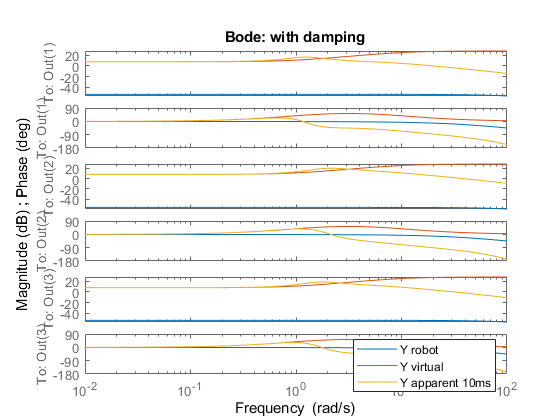

title('Bode: with damping')